# **Molecular representations and molecular descriptors**

## 1.1. SMILES strings

The simplified molecular input line-entry system (SMILES) is a specification in the form of a line notation for describing the structure of one or more molecules, using short ASCII strings. SMILES strings can be imported by most molecule editors for conversion back into two-dimensional drawings or three-dimensional models of the molecules.

In brief (Figure 1)

- Atoms are represented by their atomic symbols, with the possibility to omit H; 

- Single, double, triple and aromatic bonds can be represented with the following symbols: “−”, “=”, “#”, and “:”, respectively. Single bonds can be omitted.

- Branches are specified by enclosures in parentheses; 

- Cyclic structures are represented by breaking one single or aromatic bond in each ring and starting from one of the ring atoms. Ring “opening”/”closure” bonds are then indicated by a digit immediately following the atomic symbol at each ring closure. Aromaticity on carbon atoms can be written with lower-case letters or by alternating single and double bonds (Kekulé notation). For instance, benzene can be both written as “c1ccccc1” and “C1=CC=CC=C1”;

- Local chirality can be specified using the symbols “/” and “\”. For instance, E- and Z-1,2-difluoroethene can be written as F/C=C/F and F/C=C\F, respectively. Additionally, tetrahedral centers are often indicated using “@” (or “@@”), following the atomic symbol of the chiral atom. “@” indicates that  the listed neighbors are arranged anticlockwise, while “@@” that they appear in a clockwise order. 

- The chosen atom order for generating the SMILES does not affect the encoded 2D structure. However, several types of standardized (also known as canonicalized) SMILES generation procedures exist.

You can find a summary of SMILES theory here: [https://www.daylight.com/dayhtml/doc/theory/theory.smiles.html](https://www.daylight.com/dayhtml/doc/theory/theory.smiles.html) 

#### 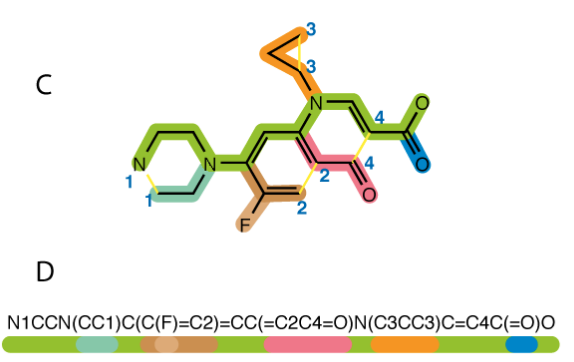

**Figure 1. **Example of the calculation of a SMILES string. Image from https://chejunkie.com/knowledge-base/convert-cas-registry-number-other/.

### Exercise 1

Which of the following molecular depictions (A, B, C, D) corresponds to the reported SMILES string?

**1.1.** SMILES: "`CCCCO`"

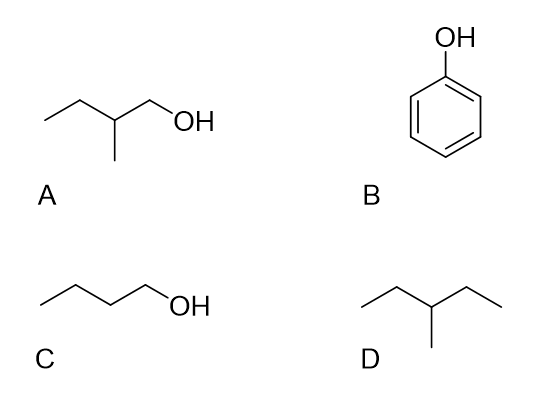

Your response:

""

ans = ""

______________________________________________________

**1.2.** SMILES: "`C1=CC=CC=C1`"

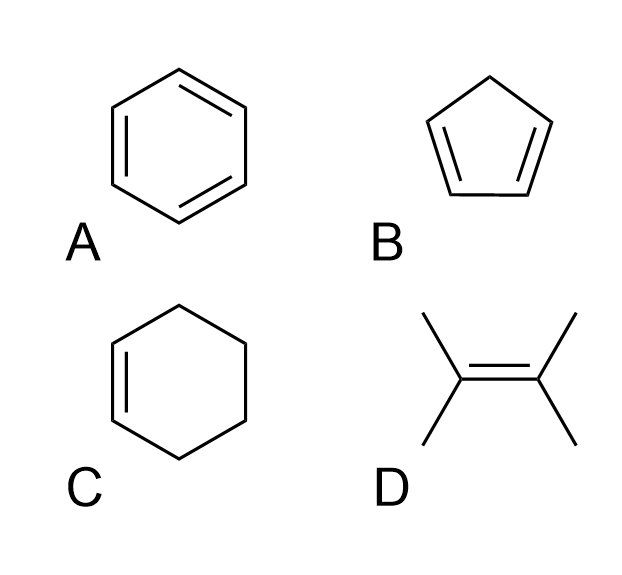

Your response:

""

**1.3.** SMILES: "`FC(F)(F)C1=CC=C(OC)C=C1`"

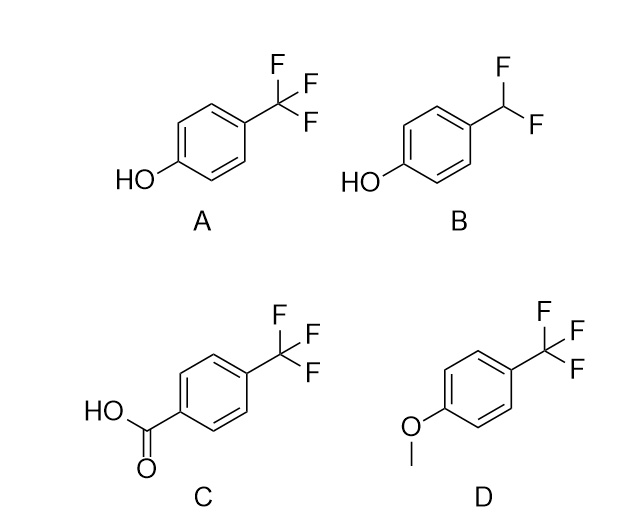

Your response:

""

### Exercise 2

Write a SMILES string for the corresponding molecule (ibuprofen)

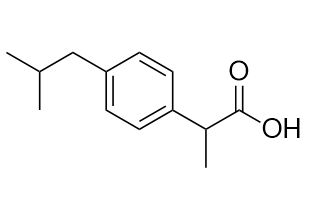

Your SMILES string:

""

====================================================================

## 1.2. Molecular descriptors

Molecular descriptors are ###TODO

In this part of the notebook, we will do some basic exercises on molecular descriptors and molecular similarity calculation. 

### 1.2.1. Real-valued descriptors

#### Exercise 1: your first molecular descriptors

Calculate molecular descriptors for two molecules, expressed as SMILES strings:

Molecule 1:

SMILES string: "ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O"

Molecule 2:

SMILES string: " "

Complete the code below, to compute the following descriptors:

- "nDB": number of double bonds

- "nO": number of oxygens

- "nCl": number of Chlorine atoms

- "nC": number of Carbon atoms

Tip!

`    strfind(string,refstring) `

finds the occurrence of `refstring `in `string`. 

Type `help strfind` to know more!

**Complete now the code below:**

smi2 = 'ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O';

nDB = []; % number of double bonds
nO = []; % number of oxygen atoms
nCl = [];  % number of chlorine atoms
nC = []; % number of carbon atoms
nN = []; % number of nitrogen atoms

**Now do the same for this next molecule:**

smi1 = '';

nDB = []; % number of double bonds
nO = []; % number of oxygen atoms
nCl = [];  % number of chlorine atoms
nC = []; % number of carbon atoms
nN = []; % number of nitrogen atoms

Attention: Note how the aromatic carbons are annotated in the two molecules. Is your code stable in case of both "C" and "c"? If not, revise. 

Also, note that the same is true for all the atoms that are aromatic (e.g., nitrogen). 

#### Exercise 2: descriptor calculation function

The code can be now turned into a function, taking the SMILES as input and providing the descriptors as output (1 x 4, array). Open the empty script called "`compute_count_descriptors.m`" (current folder) and edit following the tips contained there. 

Now you can use this function to compute the descriptors for any molecule provided as input

[descriptors, labels] = compute_count_descriptors('ClC(C)CC1=CC=C(C=C1)C(C)C(=O)O');

The function you now created can be used to compute the same descriptors for a list of molecules expressed as SMILES. 

You can check whether your code works. Running it on the following SMILES, should provide you with these descriptors:

%%% #TODO

## Real-valued descriptors

Binary descriptors are a particular type of descriptors, which capture the presence/absence of atoms, fragments and substructures in the form of 0 and 1, respectively.

#### Analyzing descriptor data

Often, molecular descriptors are computed starting from a big set of molecule identifiers (e.g., SMILES strings). The descriptors are then arranged in a table with as many rows as the number of molecules (*n*) and as many columns as the number of descriptors (*p*).

Load the dataset called "logPdataset" (present in the current folder). You can either double click on on the icon ("Current folder" window) or use the following command:

load logPdataset

In your Workspace, the following items will appear

- smiles (100x1): contains the SMILES strings corresponding to 100 molecules

- logP (100 x 1): contains the experimentally determined logP for those 100 molecules

**Exercise 1: **descriptors matrix data

In the following rows, construct a code that runs over the *n *SMILES strings contained in "smiles", and returns a matrix **X **(*n* x *p*) containing the output descriptors of the code you previously constructructed ([compute_count_descriptors.m](matlab:open('compute_count_descriptors.m')))

X = []; % empty matrix
for i = 1 : numel(smiles) % runs over the smiles strings
    % complete the code here
    
end

You can convert your data into a more compact format, the so-called MATLAB tables. Tables contain different types of objects, along with their labels. More information can be found here. [https://nl.mathworks.com/help/matlab/tables.html](https://nl.mathworks.com/help/matlab/tables.html)

X_table = array2table(X);
X_table.Properties.VariableNames = labels; % assigns the labels to the descriptors

You can view your table (X_table) within the live editor (if available for your MATLAB version)

X_table

X_table = 100×6 table
    nDB    nO    nCl    nC    nN    nc
    ___    __    ___    __    __    __

     4     4      0      8    4      0
     7     2      0     17    5      0
     2     0      0      5    1      0
     0     0      0      8    1      4
     9     3      0     14    5      0
     7     4      2      8    3      0
     2     2      0      6    0      0
     3     4      1     12    1      0
     7     0      0     12    5      0
     3     3      0     10    3      0
     2     3      0     17    1     10
     4     4      0      9    2      0
     4     4      0      8    4      0
     1     2      0      8    0      6
     1     2      0      4    3      3
     9     6      0     18    5      0


You can also use the data you obtained to quickly analyze your data, e.g.:

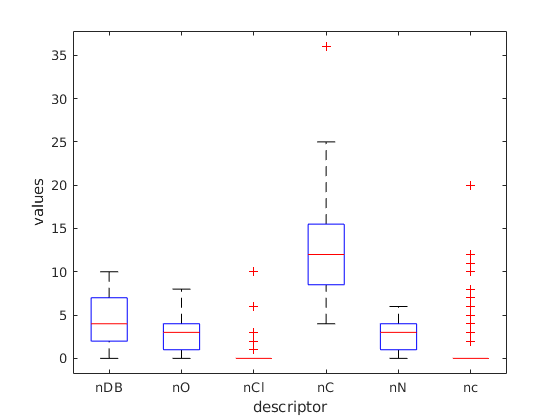

figure
boxplot(X,'Labels',labels)
xlabel('descriptor')
ylabel('values')

By using the X matrix you obtained, provide an answer to the following questions:

1. What is the most frequent type of atom present in the dataset (based on your descriptors), on average?

2. How many double bonds are, on average, possessed by the dataset molecules?

3. What is the maximum number of nitrogen atoms contained by a molecule? 

You can now save your data in the current folder under the name "myData" (or any other name you like) ;) with the following code:

save myData

**Structure-activity relationships**

Is there any empirical relationship between one (or more) descriptor(s) and the experimentally determined value of logP? 

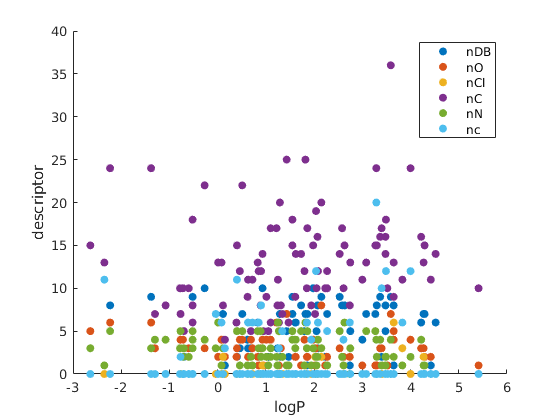

figure
for i = 1 : numel(labels)
    scatter(logP,X(:,i),'filled');
    hold on
end
xlabel('logP')
ylabel('descriptor')
legend(labels)

#### **First steps with ordinary least squares**

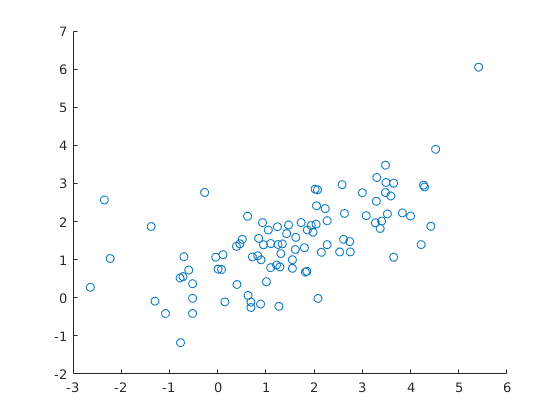

x_reg = [ones(size(X,1),1) X];
b = pinv(x_reg'*x_reg)*x_reg'*logP;
yc = x_reg*b;

scatter(logP,yc)

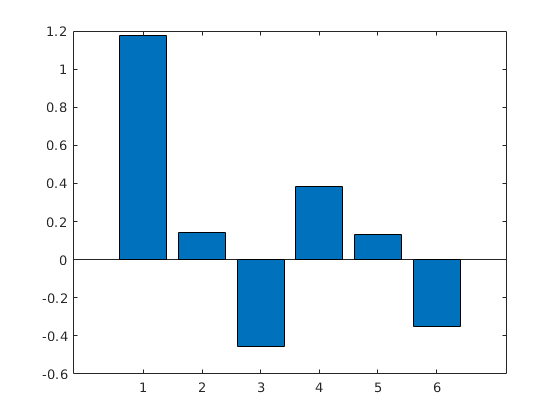

bar(b)